clc
clear

addpath("c:/git/UQ4PDE_Homeworks/Homework 4/functions/example functions/")
addpath("c:/git/UQ4PDE_Homeworks/Homework 4/functions/")
addpath("c:/git/UQ4PDE_Homeworks/Sparse Grids MATLAB/")
addpath("c:/git/UQ4PDE_Homeworks/General functions/")
addpath("c:/git/UQ4PDE_Homeworks/Homework 4/functions/partners work/")
%{
tic
anglex = -80;
angley = 10;
f = @(x) f_productpeak(x);
w = 25;
N = 2;
M = 10000;
points = 100;
x1 = linspace(0, 1, points);
[x2, y2] = meshgrid(x1, x1);
x = [x2(:), y2(:)].';
[coeff, indx, Dprod] = getLegendreCoefficientsNDPolyval(f, w, N, 'HC', M);

func_eval = LegendreSeriesNDPolyval(x, coeff, indx);
Z_exact = f(x);
Z_exact = reshape(Z_exact, points, points);
Z_approx = reshape(func_eval, points, points);

subplot(1, 2, 1);
surf(x2, y2, Z_exact);
colormap(jet)
title('Original Function');
xlabel('X');
ylabel('Y');
zlabel('Z');
view(anglex, angley)
%zlim([0, 1])
colormap(jet)

% Plot the approximation
subplot(1, 2, 2);
surf(x2, y2, Z_approx);
title('Approximation');
xlabel('X');
ylabel('Y');
zlabel('Z');
view(anglex, angley)
%zlim([0, 1])
colormap(jet)
toc
%}

%{
Z_exact = reshape(Z_exact, points, points);
Z_approx = reshape(func_eval, points, points);
surf(x2, y2, Z_approx)
figure()
surf(x2, y2, Z_exact)
%}

%{
w = 5;
type = 'HC';
Mmax = 10000;
Mstart = 1000;
N = 2;
f = @(x) f_gaussian(x);
normplot = zeros(25, 1);
counter = 1;
tic
LegPolynomCoeff = LegendrePol(w+1);
for m=Mstart:1000:Mmax
    indxset = generateMultiIndexSet(N, w, type);
    [indxsize, ~] = size(indxset);
    
    y = rand([N m]);
    phi = zeros([m 1]);
    for i=1:m
        phi(i) = f(y(:, i));
    end
    
    D = ones(m, indxsize);
    for p=1:indxsize
        for i=1:m
            for n=1:N
                D(i, p) = D(i, p)*sqrt(2*indxset(p, n)+1)*polyval(LegPolynomCoeff(:, indxset(p, n)+1), 2*y(n, i)-1);
            end
        end
    end
    Dtrans = transpose(D);
    Dprod = mtimes(Dtrans, D);
    normplot(counter) = norm(1/m*Dprod - eye(indxsize));
    counter = counter + 1;
end
toc

plot(Mstart:1000:Mmax, normplot(1:10), 'x--')
title('Stability plot', 'Interpreter', 'latex')
xlabel('$M$', 'Interpreter', 'latex')
ylabel('$\|\frac{1}{M}cond(D^TD)-I\|$', 'Interpreter', 'latex')
%savePDF('C:/Git/UQ4PDE_Homeworks/Homework 4/Plots/', 'normCond_N2_w1')
%}


wmax = 20

wmax = 20

type = 'HC';
N = 2;
f = @f_gaussian;
norm_lin = zeros(wmax, 1);
norm_quad = zeros(wmax, 1);
cond_lin = zeros(wmax, 1);
cond_quad = zeros(wmax, 1);
c = 4;
tic
for w=progress(1:wmax)
    [Mindx, ~] = size(generateMultiIndexSet(N, w, type));
    Mquad = c*Mindx^2;
    Mlin = c*Mindx;
    [coeff, indxset, DTD] = getLegendreCoefficientsNDPolyval(f, w, N, type, Mlin);
    %norm_lin(w) = norm(1/Mlin*(DTD)-eye(length(DTD)), 1);
    cond_lin(w) = cond(DTD);
    [coeff, indxset, DTD] = getLegendreCoefficientsNDPolyval(f, w, N, type, Mquad);
    cond_quad(w) = cond(DTD);
    %norm_quad(w) = norm(1/Mquad*(DTD)-eye(length(DTD)), 1);
end

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]


toc

Elapsed time is 56.962938 seconds.


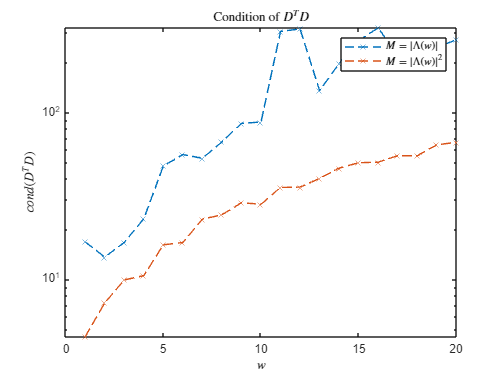


figure()
semilogy(1:wmax, cond_lin, 'x--')
hold on;
loglog(1:wmax, cond_quad, 'x--')
title('Condition of $D^TD$', 'Interpreter', 'latex')
xlabel('$w$', 'Interpreter', 'latex')
ylabel('$cond(D^TD)$', 'Interpreter', 'latex')
legend('$M=|\Lambda(w)|$', '$M=|\Lambda(w)|^2$', 'Interpreter', 'latex')

%savePDF('C:/Git/UQ4PDE_Homeworks/Homework 4/Plots/', 'norm(DTD_I)MlinvsMquad')



%{
x = linspace(0, 1, 100);
w = 1;
N = 2;
type = 'HC';
cmax = 5;
f = @(x) f_gaussian(x);
tic
[Mindx, ~] = size(generateMultiIndexSet(N, w, type));
for i=1:2
    if i==1
        cmax = 30;
        stringplot = 'Linear';
    else
        cmax = 10;
        stringplot = 'Quadratic';
    end
    condition = zeros(cmax, 1);
    M = zeros(cmax, 1);
    for c=progress(1:cmax)
        M(c) = c*Mindx^i;
        [coeff, indxset, DTD] = getLegendreCoefficientsND(f, w, N, type, M(c));
        condition(c) = cond(DTD);
    end
    semilogy(M, condition, 'x--')
    title('Condition of $D^TD$', 'Interpreter', 'latex')
    xlabel('$M$', 'Interpreter', 'latex')
    ylabel('cond$(D^TD)$', 'Interpreter', 'latex')
    legend('Linear', 'Quadratic')
    hold on;
    savePDF('C:/Git/UQ4PDE_Homeworks/Homework 4/Plots/', 'Cond(DTD)vsM_w1_N2_HC')
end
toc
%}